clc;
clear;
close all;
tic;

%% 1. Configurazione Parametri VNA
vna_ip     = '192.168.113.206';
vna_port   = 5025;
f_start    = 140e6;       % 130 MHz
f_stop     = 170e6;       % 180 MHz
n_pts      = 1001;        % Punti sweep
Z0         = 50;          % Impedenza caratteristica di riferimento [Ohm]
output_mat = ['Z_5_25.mat'];

n_avg      = 5;          % Numero di sweep mediati nel tempo
param_name = 'S12';       % Parametro di trasmissione da acquisire ('S21' o 'S12')

%% 2. Connessione e Configurazione Hardware VNA
fprintf('Connessione al VNA (%s:%d)...\n', vna_ip, vna_port);

Connessione al VNA (192.168.113.206:5025)...


t = tcpclient(vna_ip, vna_port, 'Timeout', 20);

% Configurazione iniziale dello strumento
writeline(t, '*CLS');
writeline(t, 'INST:SEL ''NA''');
writeline(t, 'INIT:CONT 0'); % Modalità manual/hold per controllo sweep da software
writeline(t, sprintf('FREQ:STAR %.0f;STOP %.0f', f_start, f_stop));
writeline(t, 'BWID 100e3');    % IF Bandwidth 1 kHz
writeline(t, sprintf('SWE:POIN %d', n_pts));
writeline(t, sprintf('CALC:PAR1:DEF %s;SEL', param_name));

%% 3. Lettura Asse Frequenze
fprintf('Lettura asse frequenze...\n');

Lettura asse frequenze...


writeline(t, 'FORM:DATA REAL,64');
writeline(t, 'SENS:FREQ:DATA?');
f_Hz = readbinblock(t, 'double');
read(t, 1, 'uint8'); % Consuma terminatore riga (LF)
f_MHz = f_Hz / 1e6;

%% 4. Acquisizione con VNA Vector Averaging (10 Ripetizioni)
fprintf('Avvio acquisizione media su %d sweep per %s...\n', n_avg, param_name);

Avvio acquisizione media su 5 sweep per S12...


writeline(t, 'FORM:DATA REAL,32');

S_buffer = zeros(n_pts, n_avg);

for k = 1:n_avg
    fprintf('  Sweep %d/%d in corso... ', k, n_avg);
    
    % Trigger sweep singolo e attesa completamento operazione (*OPC?)
    writeline(t, 'INIT;*OPC?');
    readline(t);
    
    % Lettura dati raw complessi (coppie Re, Im)
    writeline(t, 'CALC:DATA:SDAT?');
    raw_interleaved = readbinblock(t, 'single');
    read(t, 1, 'uint8'); % Consuma terminatore LF
    
    re = raw_interleaved(1:2:end);
    im = raw_interleaved(2:2:end);
    S_buffer(:, k) = complex(re, im);
    
    fprintf('Fatto.\n');
end

  Sweep 1/5 in corso... 

Fatto.


  Sweep 2/5 in corso... 

Fatto.


  Sweep 3/5 in corso... 

Fatto.


  Sweep 4/5 in corso... 

Fatto.


  Sweep 5/5 in corso... 

Fatto.



% Chiusura connessione TCP
writeline(t, 'SYST:ERR?');
err_msg = readline(t);
clear t;

% Calcolo della media complessa (Vector Average coerente)
S_param_mean = mean(S_buffer, 2);

%% 5. Calcolo Z-Trans sul Segnale Mediato
fprintf('Calcolo Z-Trans sul parametro mediato...\n');

Calcolo Z-Trans sul parametro mediato...



% Formula serie: Z = 2 * Z0 * ((1 - S) / S)
Z_trans = 2 * Z0 * ((1 - S_param_mean) ./ S_param_mean);

% Estrazione componenti
R_trans   = real(Z_trans);              % Resistenza equivalente [Ohm]
X_trans   = imag(Z_trans);              % Reattanza equivalente [Ohm]
Mag_trans = abs(Z_trans);               % Modulo dell'impedenza [Ohm]
Ph_trans  = angle(Z_trans) * (180/pi);  % Fase dell'impedenza [deg]

%% 6. Salvataggio su File .mat
misura_Ztrans.f_Hz        = f_Hz(:);
misura_Ztrans.f_MHz       = f_MHz(:);
misura_Ztrans.Z0          = Z0;
misura_Ztrans.n_avg       = n_avg;
misura_Ztrans.param_name  = param_name;
misura_Ztrans.S_raw_sweep = S_buffer;       % Tutti i 10 sweep complessi individuali
misura_Ztrans.S_mean      = S_param_mean(:); % Sweep medio complesso
misura_Ztrans.Z_trans     = Z_trans(:);
misura_Ztrans.R           = R_trans(:);
misura_Ztrans.X           = X_trans(:);
misura_Ztrans.Magnitude   = Mag_trans(:);
misura_Ztrans.Phase_deg   = Ph_trans(:);

save(output_mat, 'misura_Ztrans');
fprintf('\nParametri Z-Trans mediati salvati in "%s".\n', output_mat);


Parametri Z-Trans mediati salvati in "Z_5_25.mat".


toc;

Elapsed time is 2.507666 seconds.


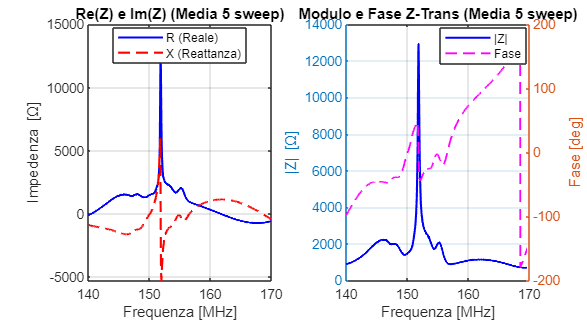


%% 7. Grafici di Controllo
figure('Color', 'w', 'Position', [100, 100, 1100, 600], ...
       'Name', sprintf('Z-Trans con Media su %d Acquisizioni', n_avg));

subplot(1, 2, 1);
plot(f_MHz, R_trans, 'b-', 'LineWidth', 1.4); hold on;
plot(f_MHz, X_trans, 'r--', 'LineWidth', 1.4);
grid on;
xlabel('Frequenza [MHz]');
ylabel('Impedenza [\Omega]');
title(sprintf('Re(Z) e Im(Z) (Media %d sweep)', n_avg));
legend('R (Reale)', 'X (Reattanza)', 'Location', 'best');

subplot(1, 2, 2);
yyaxis left;
plot(f_MHz, Mag_trans, 'b-', 'LineWidth', 1.4);
ylabel('|Z| [\Omega]');
xlabel('Frequenza [MHz]');

yyaxis right;
plot(f_MHz, Ph_trans, 'm--', 'LineWidth', 1.2);
ylabel('Fase [deg]');
grid on;
title(sprintf('Modulo e Fase Z-Trans (Media %d sweep)', n_avg));
legend('|Z|', 'Fase', 'Location', 'best');